# Numerical Methods for Optimization and Control Theory

## Daniel Kuknyo - Assignment 2

Assigned tasks: 1, 5, 10, 12

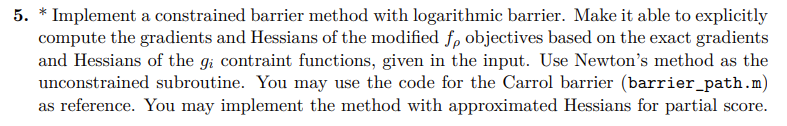

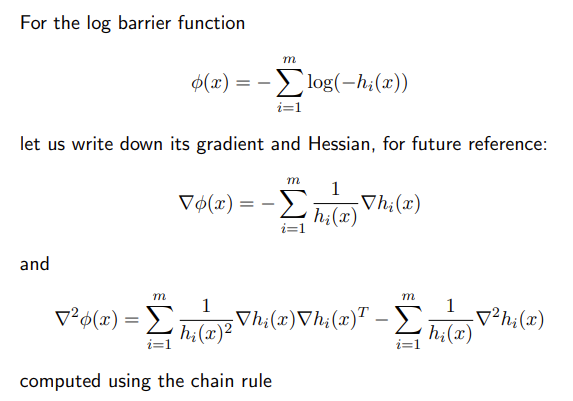

## Defining the functions

% Rosenbrock function
clc; clear all;
rr =  [-1.0, 1.2, -0.2, 1.2]; % Recommended region
  f = @(x) 100.*(x(2)-x(1).^2).^2+(1-x(1)).^2;
 df = @(x) [400.*x(1).^3-400.*x(1).*x(2)+2.*x(1)-2;200.*(x(2)-x(1).^2)];
ddf = @(x) [1200.*x(1).^2-400.*x(2)+2 -400.*x(1);-400.*x(1) 200];

% Circle constraint function
  g = @(x) x(1)^2 + x(2)^2 - 0.5;
 dg = @(x) [2*x(1) 2*x(2)];
ddg = @(x) [2 0; 0 2];

## Running the optimization

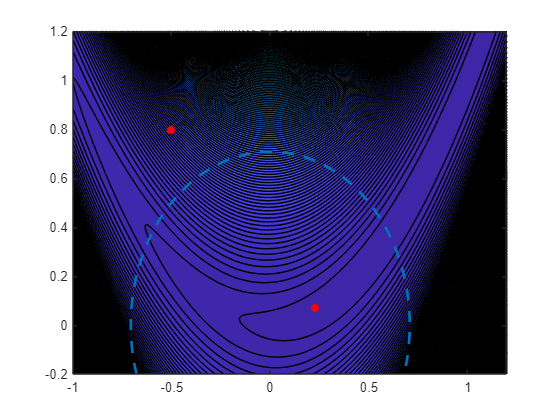

x = test_constrained_method(@barrier_path,f, df, ddf, ... % Objective function
                                          g, dg, ddg, ... % Constraint function
                                          0, 0, 0, 20, ... % Test points
                                          [-0.5; 0.8], ... % Starting point
                                          rr(1),rr(2),rr(3),rr(4),256); % Region

## Functions

function [ x ] = test_constrained_method(G,f,df,ddf,g,dg,ddg,h,dh,ddh,testpts,startpt,a,b,c,d,res)
    X = linspace(a,b,res);
    Y = linspace(c,d,res);
    Z = zeros(res,res);
    for i=1:res
        for j=1:res
            Z(i,j)=f([X(i);Y(j)]);
        end
    end

    x = zeros(testpts,2);
    x(1,:) = startpt;
    for j=2:testpts
        x(j,:) = G(f,df,ddf,g,dg,ddg,h,dh,ddh,[x(1,1);x(1,2)],j-1);
    end
    
    contourf(X,Y,Z',200); hold on
    ithcomp = @(expr,ind) expr(ind);
    try
        k = size(g(startpt),1);
        for j=1:k
            compfun = @(x,y) ithcomp(g([x;y]),j);
            fimplicit(compfun, [a,b,c,d], '--', 'LineWidth', 2.0);
        end
    catch
    end
    try
        k = size(h(startpt),1);
        for j=1:k
            compfun = @(x,y) ithcomp(h([x;y]),j);
            fimplicit(compfun, [a,b,c,d], '--', 'LineWidth', 2.0);
        end
    catch
    end
    scatter(x(:,1),x(:,2),'r','filled');
    hold off;
end

function [ x ] = barrier_path(f,df,ddf,g,dg,ddg,~,~,~,x0,iter)
    rho = 1; % 1
    mul = 2; % 2
    internal_limit = 50; % 20-50
    
    x = x0;
    for l = 1:iter
        frho = @(x) f(x) + 1/rho * log_barrier(g,x);
        dfrho = @(x) df(x) + 1/rho * log_barrier_grad(g,dg,x);
        ddfrho = @(x) ddf(x) + 1/rho * log_barrier_hessian(g, dg, ddg, x);

        x = Newton_barrier(frho,dfrho,ddfrho,x,internal_limit,g);
        rho = rho * mul;
    end
end

function gx = log_barrier(g, x) % Value of the logarithmic barrier
    gx = -sum(log(-g(x)));
end

function dgx = log_barrier_grad(g, dg, x) % Gradient of the logarithmic barrier
    dgx = -dg(x)' * (1./g(x));
end

function ddgx = log_barrier_hessian(g, dg, ddg, x) % Hessian of the logarithmic barrier
    ddgx = -sum(1./g(x).^2) * dg(x) * dg(x)' - sum(1./g(x)) * ddg(x);
end

function [ x ] = Newton_barrier(f, df, ddf, x0, iter, g)
    rho = 0.5; % Original value: 0.5
    c = 0.2; 
    x = x0;
    delta = 1e-9; % Correction constant to ensure p is a descent direction

    for k = 1:iter
        H = ddf(x);

        % Required to check if finite differencing the Hessian
        if sum(isinf(H)) > 0
            break;
        end

        [Q,D] = eig(H);
        for i = 1:size(D(:,1))
            if D(i,i) < delta
                D(i,i) = 1/delta;
            else
                D(i,i) = 1/D(i,i);
            end
        end
        p = -Q * D * Q' * df(x);
        alpha = norm(p);
        
        % Have to ensure we are searching in int G !!
        while ~all(g(x+alpha*p)<0)
            alpha = alpha*rho;
            p = -p;
        end

        gamma = Armijo_Barrier(f, df, p, x, alpha, rho, c, g);
        x = x + gamma * p;
    end
end

function [ alpha ] = Armijo_Barrier(f, df, p, x0, alpha, rho, c, g)
    f0 = f(x0);
    g0 = df(x0);
    x = x0 + alpha .* p;
    fk = f(x);
    dp = (g0'*p); % Directional derivative
    
    % Repeat until the Armijo conditions are satisfied
    while fk < f0 + c * alpha * dp && all(g(x0+alpha/rho*p)<0)
      alpha = alpha / rho;
      x = x0 + alpha * p;
      fk = f(x);
    end
    while fk > f0 + c * alpha * dp && all(g(x0+alpha*rho*p)<0)
      alpha = rho * alpha;
      x = x0 + alpha * p;
      fk = f(x);
    end
end